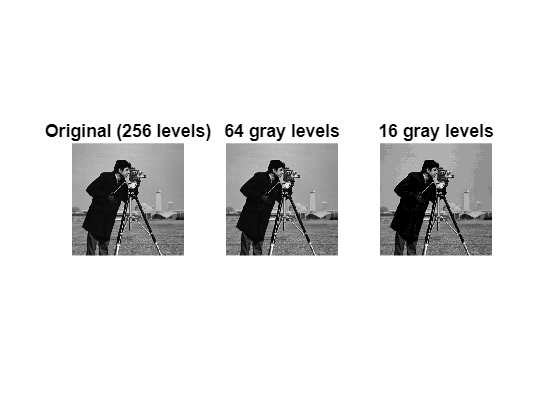

img = imread('cameraman.tif');
img2 = img;

if ndims(img2) == 3
    g = rgb2gray(img2);
else
    g = img2;
end

g64 = uint8(floor(double(g)/4)*4);
g16 = uint8(floor(double(g)/16)*16);

figure('Name','TASK 1');
subplot(1,3,1); imshow(g); title('Original (256 levels)');
subplot(1,3,2); imshow(g64); title('64 gray levels');
subplot(1,3,3); imshow(g16); title('16 gray levels');

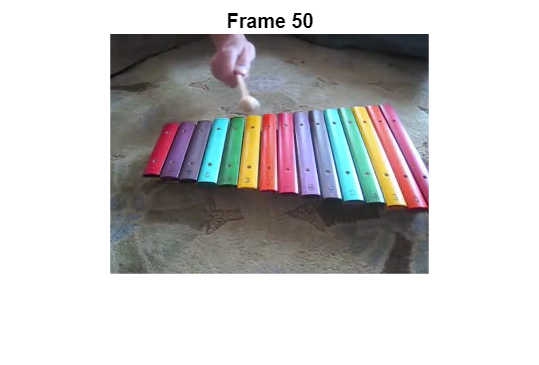


vfile = 'xylophone.mp4';

v = VideoReader(vfile);
v.CurrentTime = (50-1)/v.FrameRate;
frames_50_end = {};
while hasFrame(v)
    frames_50_end{end+1} = readFrame(v);
end
figure('Name','From 50th frame to end');
imshow(frames_50_end{1}); title('Frame 50');

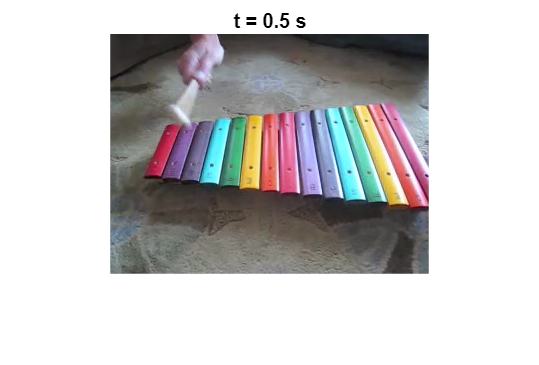


v = VideoReader(vfile);
v.CurrentTime = 0.5;
frames_from_05 = {};
while hasFrame(v)
    frames_from_05{end+1} = readFrame(v);
end
figure('Name','Starting at 0.5 s');
imshow(frames_from_05{1}); title('t = 0.5 s');

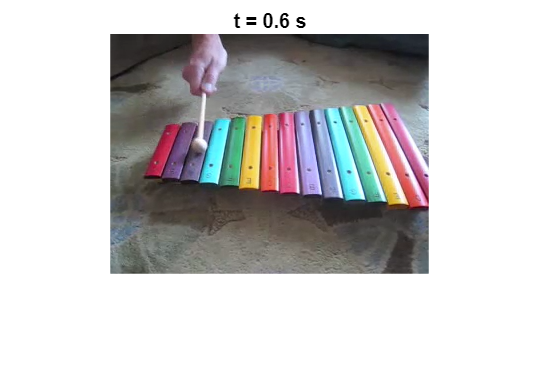


v = VideoReader(vfile);
v.CurrentTime = 0.6;
frames_06_09 = {};
while hasFrame(v) && v.CurrentTime < 0.9
    frames_06_09{end+1} = readFrame(v);
end
figure('Name','From 0.6 s to 0.9 s');
imshow(frames_06_09{1}); title('t = 0.6 s');